# Dynamic Model With Latent Variables Project

## Timothée Dangleterre and Giovanni MANCHE

Work based on the paper: A new approach to model regime switching, Chang et al. 2017, *Journal of Econometrics*

clear; clc; clearvars;
addpath('data');
addpath('utils');
addpath('core');
addpath('simulations');
addpath('visualisation');
rng(42);

### 1. Simulated data

#### 1.1 Monte Carlo simulations

In the paper, they simulate data:

- volatility model: $\sigma_{\text{low}}$ $= 0.04, \sigma_{\text{high}} = 0.12$

- mean model: $\mu_{\text{low}} = 0.6, \mu_{\text{high}} = 3, \gamma = 0.5, \sigma = 0.8$ 

They use different values of $\rho$ $= 0, -0.1, -0.2,..., -1$, and three different couples $(\alpha, \tau)$: $(0.4, 0.5), (0.8, 0.7), (1,9.63)$. They do Monte Carlo simulations: 500 observations, 1000 simulations.

% Configuration
n_obs = 500;
n_simul = 1000;
rho_values = 0:-0.1:-1;

% Alpha/Tau couples
alpha_tau_pairs = [0.4, 0.5;
                   0.8, 0.7; 
                   1, 9.63];

% Base parameters
b_vol  = create_params(0, 0, 0, 0, [0.04;0.12], 0);
b_mean = create_params(0, 0, 0, [0.6;3], 0.8, 0.5);

% MC simulations
Results = run_monte_carlo_simulations(n_obs, n_simul, rho_values, ...
                                      alpha_tau_pairs, b_vol, b_mean);

Starting Monte Carlo: 3 Pairs, 11 Rho values, 1000 Sims each.
  > Processing Pair 1/3 (Alpha=0.40, Tau=0.50)...
  > Processing Pair 2/3 (Alpha=0.80, Tau=0.70)...
  > Processing Pair 3/3 (Alpha=1.00, Tau=9.63)...
Monte Carlo simulations complete!


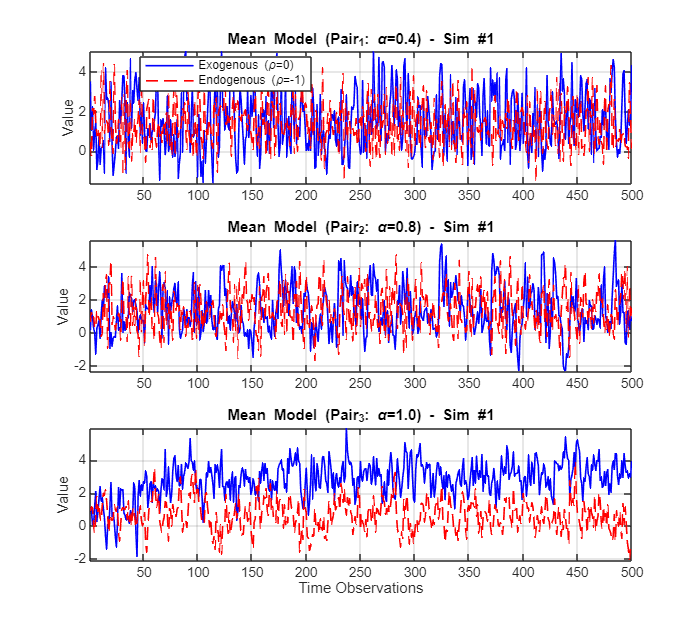

>> Chart automatically saved to: visualisation/graphs/MC_simualations_mean.png



% Visualisation
visualize_monte_carlo_check(Results, 'Mean', 1, 'visualisation/graphs/MC_simualations_mean.png');

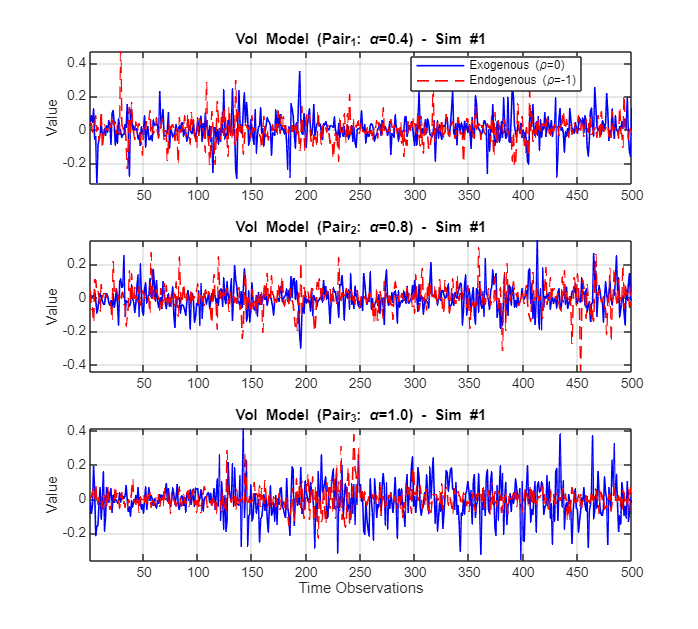

>> Chart automatically saved to: visualisation/graphs/MC_simualations_vol.png


visualize_monte_carlo_check(Results, 'Vol', 1, 'visualisation/graphs/MC_simualations_vol.png');

#### 1.2 Check

Let's check for some simulations that estimated parameters (via the CCP filter) are not *too* different from the true parameters. For that, we will extract simulations of mean and volatility model for $\rho = 0, 0.5, 1$. (à améliorer)


************************************************************


 ANALYSIS: MEAN MODEL


************************************************************


>> Processing: Sim #1 | No Rho (Exo)...



STARTING ANALYSIS: MEAN Model (k=1)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    9.071570e+02     0.000e+00     1.000e+00     0.000e+00     9.764e+01  
    1          31    9.069102e+02     0.000e+00     4.748e-03     4.637e-01     8.139e+01  
    2          43    9.037291e+02     0.000e+00     2.401e-01     7.064e-01     1.120e+02  
    3          56    8.921294e+02     0.000e+00     1.681e-01     1.169e+00     1.085e+02  
    4          72    8.917052e+02     0.000e+00     5.765e-02     5.893e-01     4.118e+01  
    5          89    8.861753e+02     0.000e+00     4.035e-02     7.747e-01     8.583e+01  
    6         105    8.845073e+02     0.000e+00     5.765e-02 


 VERIFICATION: MEAN - Sim 1 - No Rho (Exo)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu_Low       |     0.6000 |     0.5842 |    -0.0158 |       0.18 (OK)
Mu_High      |     3.0000 |     3.0331 |     0.0331 |       0.30 (OK)
Sigma        |     0.8000 |     0.8317 |     0.0317 |       0.90 (OK)
Alpha        |     0.4000 |     0.3319 |    -0.0681 |       0.72 (OK)
Tau          |     0.5000 |     0.3394 |    -0.1606 |       1.76 (OK)
Rho          |     0.0000 |    -0.0397 |    -0.0397 |       0.52 (OK)
Gamma        |     0.5000 |     0.4359 |    -0.0641 |       1.06 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #1 | Mid Rho (-0.5)...



STARTING ANALYSIS: MEAN Model (k=1)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    8.545495e+02     0.000e+00     1.000e+00     0.000e+00     1.017e+02  
    1          31    8.480650e+02     0.000e+00     4.748e-03     4.855e-01     6.334e+01  
    2          45    8.399323e+02     0.000e+00     1.176e-01     7.456e-01     5.759e+01  
    3          64    8.397291e+02     0.000e+00     1.977e-02     9.160e-01     5.776e+01  
    4          77    8.362269e+02     0.000e+00     1.681e-01     4.886e-01     8.082e+01  
    5          91    8.150620e+02     0.000e+00     1.176e-01     8.577e-01     7.038e+01  
    6         111    8.148988e+02     0.000e+00     1.384e-02 


 VERIFICATION: MEAN - Sim 1 - Mid Rho (-0.5)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu_Low       |     0.6000 |     0.6340 |     0.0340 |       0.53 (OK)
Mu_High      |     3.0000 |     3.0720 |     0.0720 |       0.81 (OK)
Sigma        |     0.8000 |     0.7590 |    -0.0410 |       1.30 (OK)
Alpha        |     0.4000 |     0.2842 |    -0.1158 |       1.25 (OK)
Tau          |     0.5000 |     0.6107 |     0.1107 |       1.27 (OK)
Rho          |    -0.5000 |    -0.3671 |     0.1329 |       1.65 (OK)
Gamma        |     0.5000 |     0.3857 |    -0.1143 |       1.60 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #1 | Endog Rho (-1)...



STARTING ANALYSIS: MEAN Model (k=1)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    8.301455e+02     0.000e+00     1.000e+00     0.000e+00     1.920e+02  
    1          31    7.958658e+02     0.000e+00     4.748e-03     9.441e-01     1.422e+02  
    2          50    7.950507e+02     0.000e+00     1.977e-02     3.402e-01     1.449e+02  
    3          68    7.908215e+02     0.000e+00     2.825e-02     7.072e-01     1.044e+02  
    4          81    7.771708e+02     0.000e+00     1.681e-01     8.713e-01     1.259e+02  
    5          95    7.531140e+02     0.000e+00     1.176e-01     7.616e-01     1.270e+02  
    6         107    7.253584e+02     0.000e+00     2.401e-01 


 VERIFICATION: MEAN - Sim 1 - Endog Rho (-1)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu_Low       |     0.6000 |     0.5842 |    -0.0158 |       0.01 (OK)
Mu_High      |     3.0000 |     2.9434 |    -0.0566 |       0.01 (OK)
Sigma        |     0.8000 |     0.7823 |    -0.0177 |       0.01 (OK)
Alpha        |     0.4000 |     0.1813 |    -0.2187 |       0.05 (OK)
Tau          |     0.5000 |     0.4807 |    -0.0193 |       0.00 (OK)
Rho          |    -1.0000 |    -0.9900 |     0.0100 |       0.01 (OK)
Gamma        |     0.5000 |     0.2646 |    -0.2354 |       0.07 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #287 | No Rho (Exo)...



STARTING ANALYSIS: MEAN Model (k=1)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    8.606195e+02     0.000e+00     1.000e+00     0.000e+00     8.581e+01  
    1          32    8.571847e+02     0.000e+00     3.323e-03     2.254e-01     7.850e+01  
    2          44    8.520990e+02     0.000e+00     2.401e-01     4.832e-01     1.139e+02  
    3          53    8.504936e+02     0.000e+00     7.000e-01     1.929e+00     4.732e+01  
    4          67    8.504493e+02     0.000e+00     1.176e-01     1.848e+00     5.558e+01  
    5          83    8.499843e+02     0.000e+00     5.765e-02     5.627e-01     7.540e+01  
    6          95    8.497966e+02     0.000e+00     2.401e-01 


 VERIFICATION: MEAN - Sim 287 - No Rho (Exo)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu_Low       |     0.6000 |     0.6367 |     0.0367 |       0.42 (OK)
Mu_High      |     3.0000 |     3.0597 |     0.0597 |       0.45 (OK)
Sigma        |     0.8000 |     0.8126 |     0.0126 |       0.36 (OK)
Alpha        |     0.4000 |     0.4322 |     0.0322 |       0.31 (OK)
Tau          |     0.5000 |     0.7581 |     0.2581 |       2.13 (!)
Rho          |     0.0000 |     0.0542 |     0.0542 |       0.52 (OK)
Gamma        |     0.5000 |     0.4897 |    -0.0103 |       0.17 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #287 | Mid Rho (-0.5)...



STARTING ANALYSIS: MEAN Model (k=1)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    8.874712e+02     0.000e+00     1.000e+00     0.000e+00     9.843e+01  
    1          31    8.785204e+02     0.000e+00     4.748e-03     4.705e-01     5.987e+01  
    2          45    8.702678e+02     0.000e+00     1.176e-01     8.148e-01     4.895e+01  
    3          63    8.702325e+02     0.000e+00     2.825e-02     9.784e-01     4.848e+01  
    4          75    8.595183e+02     0.000e+00     2.401e-01     8.530e-01     8.809e+01  
    5          89    8.510470e+02     0.000e+00     1.176e-01     7.829e-01     9.540e+01  
    6         112    8.494359e+02     0.000e+00     4.748e-03 


 VERIFICATION: MEAN - Sim 287 - Mid Rho (-0.5)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu_Low       |     0.6000 |     0.5930 |    -0.0070 |       0.10 (OK)
Mu_High      |     3.0000 |     3.1528 |     0.1528 |       1.51 (OK)
Sigma        |     0.8000 |     0.8302 |     0.0302 |       0.84 (OK)
Alpha        |     0.4000 |     0.1905 |    -0.2095 |       2.33 (!)
Tau          |     0.5000 |     0.5587 |     0.0587 |       0.70 (OK)
Rho          |    -0.5000 |    -0.5013 |    -0.0013 |       0.02 (OK)
Gamma        |     0.5000 |     0.4387 |    -0.0613 |       1.27 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #287 | Endog Rho (-1)...



STARTING ANALYSIS: MEAN Model (k=1)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    8.365315e+02     0.000e+00     1.000e+00     0.000e+00     1.951e+02  
    1          31    8.002952e+02     0.000e+00     4.748e-03     9.652e-01     1.305e+02  
    2          50    7.977146e+02     0.000e+00     1.977e-02     3.089e-01     1.322e+02  
    3          68    7.914803e+02     0.000e+00     2.825e-02     7.620e-01     9.340e+01  
    4          81    7.759385e+02     0.000e+00     1.681e-01     1.005e+00     1.162e+02  
    5          94    7.691196e+02     0.000e+00     1.681e-01     1.359e+00     1.293e+02  
    6         110    7.672941e+02     0.000e+00     5.765e-02 


 VERIFICATION: MEAN - Sim 287 - Endog Rho (-1)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu_Low       |     0.6000 |     0.6767 |     0.0767 |       0.05 (OK)
Mu_High      |     3.0000 |     2.9437 |    -0.0563 |       0.72 (OK)
Sigma        |     0.8000 |     0.8319 |     0.0319 |       0.02 (OK)
Alpha        |     0.4000 |     0.1651 |    -0.2349 |       0.10 (OK)
Tau          |     0.5000 |     0.5027 |     0.0027 |       0.00 (OK)
Rho          |    -1.0000 |    -0.9900 |     0.0100 |       0.01 (OK)
Gamma        |     0.5000 |     0.2473 |    -0.2527 |       0.10 (OK)
-------------------------------------------------------------------------



************************************************************


 ANALYSIS: VOL MODEL


************************************************************


>> Processing: Sim #1 | No Rho (Exo)...



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7   -5.949835e+02     0.000e+00     1.000e+00     0.000e+00     9.038e+02  
    1          46   -5.973288e+02     0.000e+00     1.104e-05     9.986e-03     4.713e+02  
    2          63   -6.001076e+02     0.000e+00     2.825e-02     6.260e-01     6.608e+02  
    3          94   -6.007693e+02     0.000e+00     1.916e-04     2.519e-01     5.479e+02  
    4         107   -6.037614e+02     0.000e+00     1.176e-01     2.060e-01     1.172e+03  
    5         118   -6.059737e+02     0.000e+00     2.401e-01     6.134e-01     7.729e+02  
    6         131   -6.063029e+02     0.000e+00   


 VERIFICATION: VOL - Sim 1 - No Rho (Exo)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu           |     0.0000 |     0.0020 |     0.0020 |       0.78 (OK)
Sigma_Low    |     0.0400 |     0.0421 |     0.0021 |       0.69 (OK)
Sigma_High   |     0.1200 |     0.1313 |     0.0113 |       1.10 (OK)
Alpha        |     0.4000 |     0.6875 |     0.2875 |       2.08 (!)
Tau          |     0.5000 |     0.6634 |     0.1634 |       1.05 (OK)
Rho          |     0.0000 |    -0.1345 |    -0.1345 |       0.97 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #1 | Mid Rho (-0.5)...



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7   -6.102542e+02     0.000e+00     1.000e+00     0.000e+00     6.338e+02  
    1          46   -6.112085e+02     0.000e+00     1.104e-05     7.008e-03     3.773e+02  
    2          63   -6.128865e+02     0.000e+00     2.825e-02     7.850e-01     1.384e+03  
    3          97   -6.135159e+02     0.000e+00     6.571e-05     2.550e-01     4.220e+02  
    4         124   -6.135643e+02     0.000e+00     7.979e-04     4.036e-02     4.304e+02  
    5         133   -6.178211e+02     0.000e+00     4.900e-01     3.806e-01     3.253e+02  
    6         145   -6.222403e+02     0.000e+00   


 VERIFICATION: VOL - Sim 1 - Mid Rho (-0.5)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu           |     0.0000 |     0.0011 |     0.0011 |       0.40 (OK)
Sigma_Low    |     0.0400 |     0.0487 |     0.0087 |       3.00 (!)
Sigma_High   |     0.1200 |     0.1338 |     0.0138 |       1.16 (OK)
Alpha        |     0.4000 |     0.2987 |    -0.1013 |       0.69 (OK)
Tau          |     0.5000 |     0.6402 |     0.1402 |       1.00 (OK)
Rho          |    -0.5000 |    -0.8179 |    -0.3179 |       2.98 (!)
-------------------------------------------------------------------------


>> Processing: Sim #1 | Endog Rho (-1)...



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7   -6.872780e+02     0.000e+00     1.000e+00     0.000e+00     6.466e+02  
    1          47   -6.874819e+02     0.000e+00     7.731e-06     2.596e-03     6.321e+02  
    2          64   -6.906930e+02     0.000e+00     2.825e-02     9.304e-01     1.108e+03  
    3         101   -6.907470e+02     0.000e+00     2.254e-05     1.354e-01     3.407e+02  
    4         123   -6.908554e+02     0.000e+00     4.748e-03     7.760e-02     5.322e+02  
    5         134   -6.924075e+02     0.000e+00     2.401e-01     1.619e-01     1.299e+03  
    6         142   -6.980234e+02     0.000e+00   

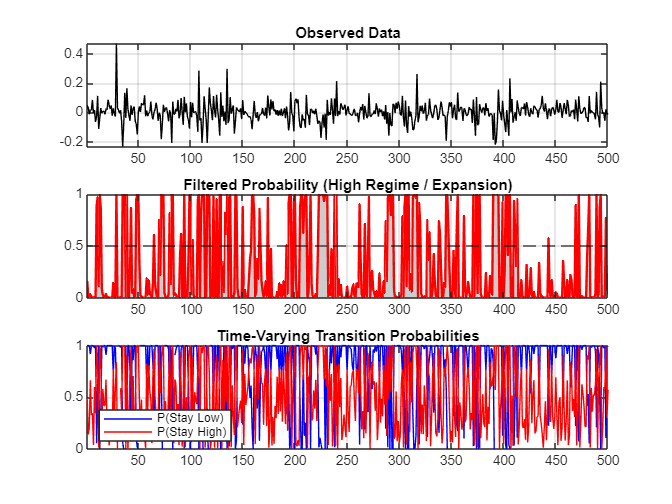


 VERIFICATION: VOL - Sim 1 - Endog Rho (-1)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu           |     0.0000 |     0.0014 |     0.0014 |       0.11 (OK)
Sigma_Low    |     0.0400 |     0.0401 |     0.0001 |       0.04 (OK)
Sigma_High   |     0.1200 |     0.1142 |    -0.0058 |       0.80 (OK)
Alpha        |     0.4000 |     0.4897 |     0.0897 |       0.11 (OK)
Tau          |     0.5000 |     0.6160 |     0.1160 |       0.27 (OK)
Rho          |    -1.0000 |    -0.9900 |     0.0100 |       0.01 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #287 | No Rho (Exo)...



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7   -6.631090e+02     0.000e+00     1.000e+00     0.000e+00     2.748e+02  
    1          46   -6.631182e+02     0.000e+00     1.104e-05     1.872e-03     3.369e+02  
    2          83   -6.631238e+02     0.000e+00     2.254e-05     6.649e-04     2.655e+02  
    3          98   -6.692375e+02     0.000e+00     5.765e-02     1.155e+00     3.398e+02  
    4         127   -6.692618e+02     0.000e+00     3.910e-04     8.064e-02     3.529e+02  
    5         136   -6.801325e+02     0.000e+00     4.900e-01     9.540e-01     1.011e+03  
    6         146   -6.811467e+02     0.000e+00   

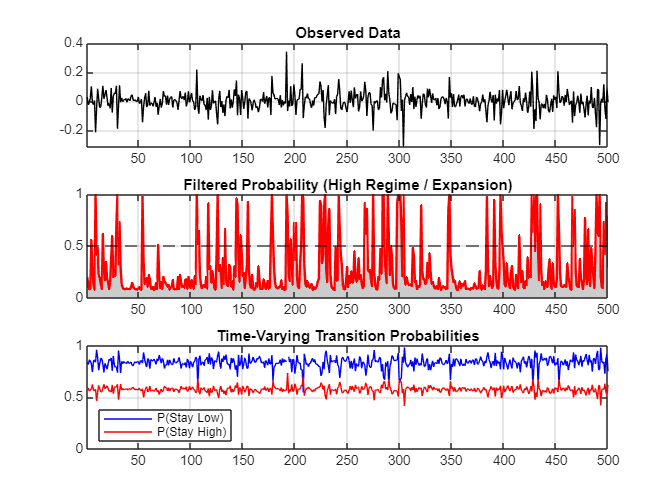


 VERIFICATION: VOL - Sim 287 - No Rho (Exo)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu           |     0.0000 |     0.0040 |     0.0040 |       1.73 (OK)
Sigma_Low    |     0.0400 |     0.0401 |     0.0001 |       0.04 (OK)
Sigma_High   |     0.1200 |     0.1123 |    -0.0077 |       0.89 (OK)
Alpha        |     0.4000 |     0.6267 |     0.2267 |       1.57 (OK)
Tau          |     0.5000 |     0.7603 |     0.2603 |       1.25 (OK)
Rho          |     0.0000 |     0.1527 |     0.1527 |       0.98 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #287 | Mid Rho (-0.5)...



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7   -6.666796e+02     0.000e+00     1.000e+00     0.000e+00     4.141e+02  
    1          47   -6.670716e+02     0.000e+00     7.731e-06     3.208e-03     2.281e+02  
    2          64   -6.680503e+02     0.000e+00     2.825e-02     7.227e-01     1.491e+03  
    3         100   -6.687557e+02     0.000e+00     3.220e-05     3.012e-01     2.877e+02  
    4         127   -6.687835e+02     0.000e+00     7.979e-04     3.870e-02     2.236e+02  
    5         136   -6.704971e+02     0.000e+00     4.900e-01     2.974e-01     1.975e+02  
    6         149   -6.724764e+02     0.000e+00   

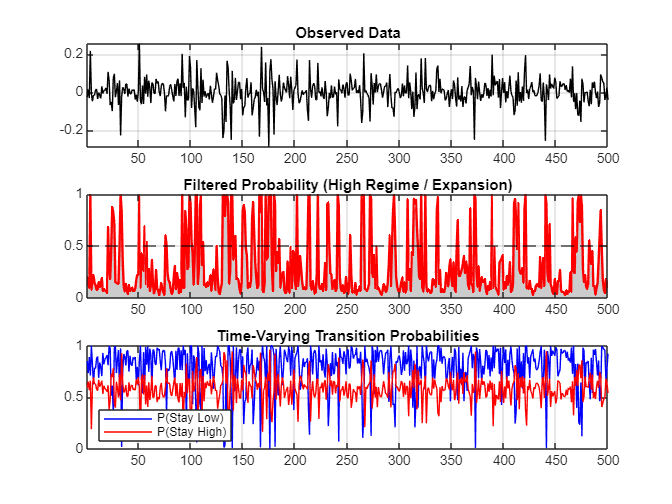


 VERIFICATION: VOL - Sim 287 - Mid Rho (-0.5)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu           |     0.0000 |     0.0017 |     0.0017 |       0.71 (OK)
Sigma_Low    |     0.0400 |     0.0395 |    -0.0005 |       0.21 (OK)
Sigma_High   |     0.1200 |     0.1145 |    -0.0055 |       0.75 (OK)
Alpha        |     0.4000 |     0.6044 |     0.2044 |       2.07 (!)
Tau          |     0.5000 |     0.6405 |     0.1405 |       1.14 (OK)
Rho          |    -0.5000 |    -0.5463 |    -0.0463 |       0.44 (OK)
-------------------------------------------------------------------------


>> Processing: Sim #287 | Endog Rho (-1)...



STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7   -6.760571e+02     0.000e+00     1.000e+00     0.000e+00     1.667e+03  
    1          47   -6.761213e+02     0.000e+00     7.731e-06     1.313e-03     1.647e+03  
    2          64   -6.786644e+02     0.000e+00     2.825e-02     1.197e+00     4.686e+02  
    3          98   -6.790006e+02     0.000e+00     6.571e-05     9.320e-02     1.718e+02  
    4         109   -6.851984e+02     0.000e+00     2.401e-01     3.122e-01     3.741e+03  
    5         126   -6.943590e+02     0.000e+00     2.825e-02     7.974e-01     7.465e+02  
    6         134   -6.970234e+02     0.000e+00   

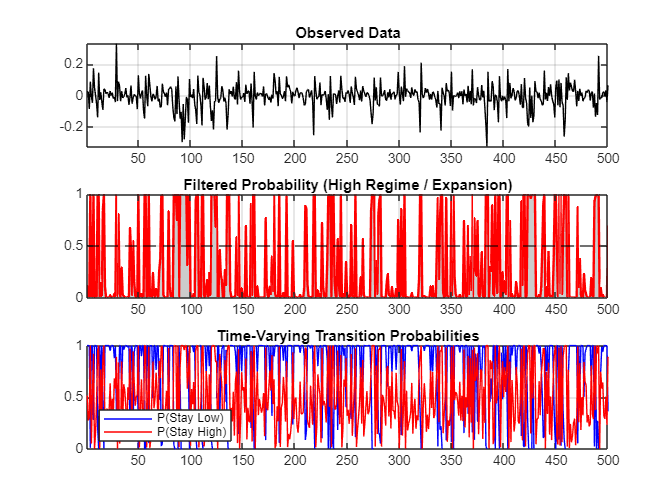


 VERIFICATION: VOL - Sim 287 - Endog Rho (-1)
Param        | TRUE       | ESTIMATED  | BIAS       | Z-Score   
-------------------------------------------------------------------------
Mu           |     0.0000 |    -0.0029 |    -0.0029 |       0.14 (OK)
Sigma_Low    |     0.0400 |     0.0375 |    -0.0025 |       0.47 (OK)
Sigma_High   |     0.1200 |     0.1294 |     0.0094 |       0.83 (OK)
Alpha        |     0.4000 |     0.5121 |     0.1121 |       0.07 (OK)
Tau          |     0.5000 |     0.6289 |     0.1289 |       0.75 (OK)
Rho          |    -1.0000 |    -0.9900 |     0.0100 |       0.01 (OK)
-------------------------------------------------------------------------


% Creation of a output text file that will contain the results
output_filename = 'Results_Table.txt';
fid = fopen(output_filename, 'w');
if fid == -1
    error('Cannot open the file %s', output_filename);
end

% Function to print both in the output window and in the text file
function dual_print(fid, varargin)
    fprintf(varargin{:});
    if fid > 0
        fprintf(fid, varargin{:});
    end
end

% Simulation indexes we want to check
sim_indices = [1, 287];

% Rhos to try : 3rd dimension index in the tensor, value of rho
rho_scenarios = {
    1,   0.0,  'No Rho (Exo)';
    6,  -0.5,  'Mid Rho (-0.5)';
    11, -1.0,  'Endog Rho (-1)'
};

% Base parameters
base_mean = [0.6; 3.0; 0.8; 0.4; 0.5; NaN; 0.5]; 
names_mean = {'Mu_Low', 'Mu_High', 'Sigma', 'Alpha', 'Tau', 'Rho', 'Gamma'};

base_vol  = [0.0; 0.04; 0.12; 0.4; 0.5; NaN];
names_vol = {'Mu', 'Sigma_Low', 'Sigma_High', 'Alpha', 'Tau', 'Rho'};

%% MAIN LOOP
% Name in the Results strcuture
models_list = {'Mean', 'Vol'};

for m = 1:length(models_list)
    model_type = models_list{m};
    is_mean = strcmp(model_type, 'Mean');
    
    % Specific configuration depending on the model
    if is_mean
        k_lag = 1;
        run_type = 'mean';
        base_true_params = base_mean;
        param_names = names_mean;
        rho_pos = 6; % Position of rho in the parameter vector
    else
        k_lag = 0;
        run_type = 'volatility'; 
        base_true_params = base_vol;
        param_names = names_vol;
        rho_pos = 6; 
    end
    
    % Print both in the output window and in the text file
    dual_print(fid, '\n************************************************************\n');
    dual_print(fid, ' ANALYSIS: %s MODEL\n', upper(model_type));
    dual_print(fid, '************************************************************\n');

    % LOOP ON THE SIMULATIONS
    for s_idx = 1:length(sim_indices)
        curr_sim = sim_indices(s_idx);
        
        % LOOP ON THE VALUES OF RHO (0, -0.5, -1)
        for r = 1:size(rho_scenarios, 1)
            curr_rho_idx = rho_scenarios{r, 1};
            curr_rho_val = rho_scenarios{r, 2};
            curr_rho_lbl = rho_scenarios{r, 3};
            
            % 1. Simulated data extraction
            if is_mean
                y = Results.Pair_1.Mean(:, curr_sim, curr_rho_idx);
            else
                y = Results.Pair_1.Vol(:, curr_sim, curr_rho_idx);
            end
            
            % 2. Start analysis
            fprintf('>> Processing: Sim #%d | %s...\n', curr_sim, curr_rho_lbl);
            output = run_full_analysis(y, k_lag, run_type, true, true);
            
            % 3. True parameters (for the table)
            true_params = base_true_params;
            true_params(rho_pos) = curr_rho_val; 
            
            % 4. Print table
            title_str = sprintf('%s - Sim %d - %s', upper(model_type), curr_sim, curr_rho_lbl);
            display_verification_table(title_str, output, true_params, param_names);
            dual_print(fid, '\n');
        end
    end
end

fclose(fid);
fprintf('Analysis done. Results saved in %s\n', output_filename);

Error using disp
Too many input arguments.

### 2. Hamilton

fprintf('Loading Hamilton Data...\n');

Loading Hamilton Data...


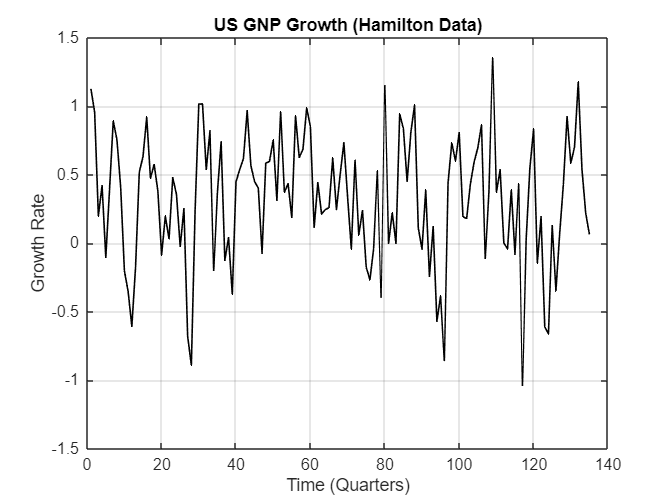


% Load the Excel file (Ensure Hamilton.xlsx is in the folder)
try
    dataGDP = readmatrix('Hamilton.xlsx', 'Sheet', 'GNP82', 'NumHeaderLines', 1);
    y = dataGDP(:, 2); % Assuming Column 2 is the growth rate
    y = y(~isnan(y));  % Remove NaNs
catch
    error('Could not load Hamilton.xlsx. Please ensure the file is in the current directory.');
end

% Optional: Plot raw data
figure('Name', 'Raw Data Check', 'Color', 'w');
plot(y, 'k', 'LineWidth', 1); 
title('US GNP Growth (Hamilton Data)'); 
xlabel('Time (Quarters)'); ylabel('Growth Rate'); grid on;


STARTING ANALYSIS: MEAN Model (k=4)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for MEAN model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          11    8.182314e+01     0.000e+00     1.000e+00     0.000e+00     5.796e+01  
    1          36    7.903324e+01     0.000e+00     6.782e-03     2.823e-01     6.528e+01  
    2          56    7.886029e+01     0.000e+00     4.035e-02     1.705e-01     4.976e+01  
    3          75    7.812472e+01     0.000e+00     5.765e-02     1.629e-01     2.528e+01  
    4          93    7.783899e+01     0.000e+00     8.235e-02     2.252e-01     2.308e+01  
    5         110    7.767374e+01     0.000e+00     1.176e-01     4.587e-01     1.118e+02  
    6         127    7.748136e+01     0.000e+00     1.176e-01 

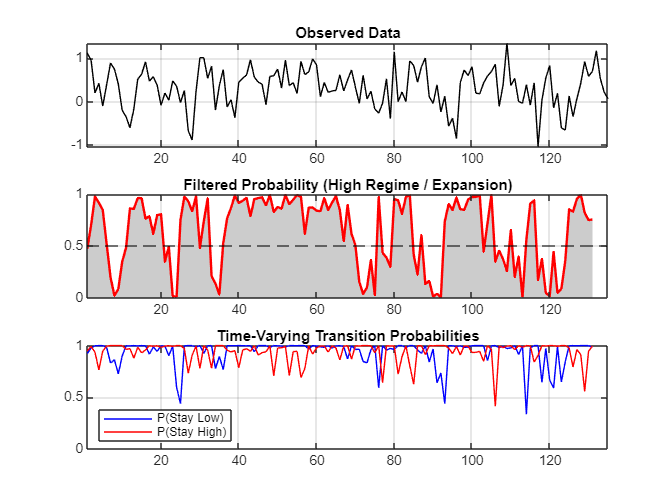


%% 2. RUN ANALYSIS
% Configuration for Hamilton (1989) replication:
% - AR(4) process on GNP growth
% - Mean Switching model
% - Compare against Exogenous (Rho=0) hypothesis

true_k = 4; 
model_type = 'mean';
run_exog_test = true; 

% Execute the full modular analysis
output = run_full_analysis(y, true_k, model_type, run_exog_test, true);


%% 3. DISPLAY RESULTS: ENDOGENOUS MODEL (Chang et al.)

est = output.params_estimated;
se  = output.se;

% Calculate t-stats
t_stats = est ./ se;

% Dynamic Parameter Naming (Adapts to k)
% Order: [Mu_L, Mu_H, Sigma, Alpha, Tau, Rho, Gamma_1...Gamma_k]
param_names = { ...
    'Mu (Recession)', ...
    'Mu (Expansion)', ...
    'Sigma', ...
    'Alpha (Latent)', ...
    'Tau (Threshold)', ...
    'Rho (Endog)'
};

% Add Gamma names dynamically based on k
for j = 1:true_k
    param_names{end+1} = sprintf('Gamma (AR%d)', j);
end

fprintf('\n============================================================\n');

fprintf(' ESTIMATION RESULTS: ENDOGENOUS MODEL (Chang et al.)\n');

 ESTIMATION RESULTS: ENDOGENOUS MODEL (Chang et al.)


fprintf('============================================================\n');

fprintf('%-20s | %-10s | %-10s | %-8s\n', 'Parameter', 'Estimate', 'Std.Err', 't-Stat');

Parameter            | Estimate   | Std.Err    | t-Stat  


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for i = 1:length(est)
    val = est(i);
    std_err = se(i);
    ts = t_stats(i);
    
    % Significance stars
    sig_star = '';
    if abs(ts) > 1.645, sig_star = '*';   end % 10%
    if abs(ts) > 1.96,  sig_star = '**';  end % 5%
    if abs(ts) > 2.576, sig_star = '***'; end % 1%
    
    fprintf('%-20s | %10.4f | %10.4f | %8.2f %s\n', ...
        param_names{i}, val, std_err, ts, sig_star);
end

Mu (Recession)       |    -0.0261 |     0.0614 |    -0.43 
Mu (Expansion)       |     0.5301 |     0.0398 |    13.31 ***
Sigma                |     0.3478 |     0.0247 |    14.09 ***
Alpha (Latent)       |     0.9331 |     0.0415 |    22.50 ***
Tau (Threshold)      |    -0.5122 |     0.9442 |    -0.54 
Rho (Endog)          |    -0.8507 |     0.2355 |    -3.61 ***
Gamma (AR1)          |     0.1057 |     0.1082 |     0.98 
Gamma (AR2)          |     0.0578 |     0.0939 |     0.61 
Gamma (AR3)          |    -0.2783 |     0.1091 |    -2.55 **
Gamma (AR4)          |    -0.1529 |     0.0990 |    -1.54 


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Log-Likelihood : %.4f\n', output.loglik);

Log-Likelihood : -70.9486



% Display LR Test Results
if isfield(output, 'comparison')
    fprintf('\nLIKELIHOOD RATIO TEST (Endogeneity Check):\n');
    fprintf('  H0: Rho = 0 (Exogenous model is sufficient)\n');
    fprintf('  LR Statistic: %.4f\n', output.comparison.lr_stat);
    fprintf('  P-Value:      %.4f\n', output.comparison.p_value);
    
    if output.comparison.p_value < 0.05
        fprintf('  -> RESULT: REJECT H0. Endogeneity is significant.\n');
    else
        fprintf('  -> RESULT: FAIL TO REJECT H0. No strong evidence for endogeneity.\n');
    end
end


LIKELIHOOD RATIO TEST (Endogeneity Check):


  H0: Rho = 0 (Exogenous model is sufficient)


  LR Statistic: 2.4319


  P-Value:      0.1189


  -> RESULT: FAIL TO REJECT H0. No strong evidence for endogeneity.


fprintf('============================================================\n');



%% 4. DISPLAY RESULTS: EXOGENOUS MODEL (Standard Hamilton)

if isfield(output, 'comparison') && isfield(output.comparison, 'res_exo')
    
    % Extract Exogenous Results
    res_exo = output.comparison.res_exo;
    est_exo = res_exo.params;
    se_exo  = res_exo.se;

    % Parameter Names (Same order, but Rho is fixed)
    param_names_exo = param_names;
    param_names_exo{6} = 'Rho (FIXED=0)'; 

    fprintf('\n============================================================\n');
    fprintf(' ESTIMATION RESULTS: EXOGENOUS MODEL (Standard Hamilton)\n');
    fprintf('============================================================\n');
    fprintf('%-20s | %-10s | %-10s | %-8s\n', 'Parameter', 'Estimate', 'Std.Err', 't-Stat');
    fprintf('------------------------------------------------------------\n');

    for i = 1:length(est_exo)
        val = est_exo(i);
        std_err = se_exo(i);
        
        % Special handling for Rho (Fixed parameter has 0 SE)
        if std_err < 1e-6
            fprintf('%-20s | %10.4f | %10s | %8s\n', param_names_exo{i}, val, '(Fixed)', '-');
        else
            ts = val / std_err;
            sig_star = '';
            if abs(ts) > 1.645, sig_star = '*';   end
            if abs(ts) > 1.96,  sig_star = '**';  end
            if abs(ts) > 2.576, sig_star = '***'; end
            
            fprintf('%-20s | %10.4f | %10.4f | %8.2f %s\n', ...
                param_names_exo{i}, val, std_err, ts, sig_star);
        end
    end
    fprintf('------------------------------------------------------------\n');
    fprintf('Log-Likelihood : %.4f\n', res_exo.loglik);
    fprintf('============================================================\n');

else
    fprintf('Warning: Exogenous results not found. Make sure run_exog_test = true.\n');
end

 ESTIMATION RESULTS: EXOGENOUS MODEL (Standard Hamilton)


Parameter            | Estimate   | Std.Err    | t-Stat  


------------------------------------------------------------


Mu (Recession)       |    -0.1525 |     0.1203 |    -1.27 
Mu (Expansion)       |     0.5090 |     0.0327 |    15.57 ***
Sigma                |     0.3336 |     0.0345 |     9.67 ***
Alpha (Latent)       |     0.8717 |     0.0824 |    10.58 ***
Tau (Threshold)      |    -1.1268 |     0.6461 |    -1.74 *
Rho (FIXED=0)        |     0.0000 |     1.0000 |     0.00 
Gamma (AR1)          |     0.0089 |     0.3011 |     0.03 
Gamma (AR2)          |    -0.0666 |     0.1487 |    -0.45 
Gamma (AR3)          |    -0.2475 |     0.1287 |    -1.92 *
Gamma (AR4)          |    -0.2019 |     0.1176 |    -1.72 *


------------------------------------------------------------


Log-Likelihood : -72.1645


### 3. VIX

%% 1. SETUP AND DATA LOADING (VIX)
% We use specific variable names to avoid conflict with Hamilton variables
fprintf('Loading VIX Data...\n');

Loading VIX Data...



try
    % Load Excel file: VIX.xlsx
    % We assume the data is in Column 2
    raw_data_vix = readmatrix('VIX.xlsx', 'Sheet', 'Monthly', 'NumHeaderLines', 1);
    
    % Extract variable
    y_vix = raw_data_vix(:, 2); 
    
    % Optional: Use Log-VIX (Common in literature for volatility modeling)
    % Uncomment the next line if optimization fails with raw levels
    % y_vix = log(y_vix); 

    % Remove NaNs
    y_vix = y_vix(~isnan(y_vix));  
    
    fprintf('Loaded %d observations from VIX.xlsx\n', length(y_vix));
catch
    error('Could not load VIX.xlsx. Please ensure the file is in the current directory.');
end

Loaded 430 observations from VIX.xlsx


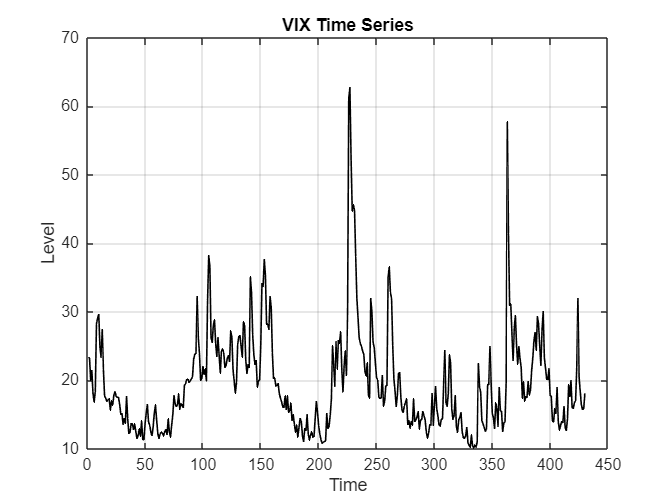


% Plot VIX Data
figure('Name', 'VIX Data Check', 'Color', 'w');
plot(y_vix, 'k', 'LineWidth', 1); 
title('VIX Time Series'); 
xlabel('Time'); ylabel('Level'); grid on;


STARTING ANALYSIS: VOLATILITY Model (k=0)
1. Estimating Endogenous Model (Free Rho)...
Starting Optimization for VOLATILITY model...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    1.468214e+03     0.000e+00     1.000e+00     0.000e+00     8.929e+01  
    1          16    1.465062e+03     0.000e+00     4.900e-01     5.861e+00     2.366e+01  
    2          24    1.407901e+03     0.000e+00     7.000e-01     4.290e+00     1.232e+02  
    3          38    1.405510e+03     0.000e+00     8.235e-02     6.631e-01     4.789e+01  
    4          52    1.376042e+03     0.000e+00     8.235e-02     5.738e+00     2.178e+01  
    5          63    1.373959e+03     0.000e+00     2.401e-01     1.110e+00     2.591e+01  
    6          72    1.356615e+03     0.000e+00   

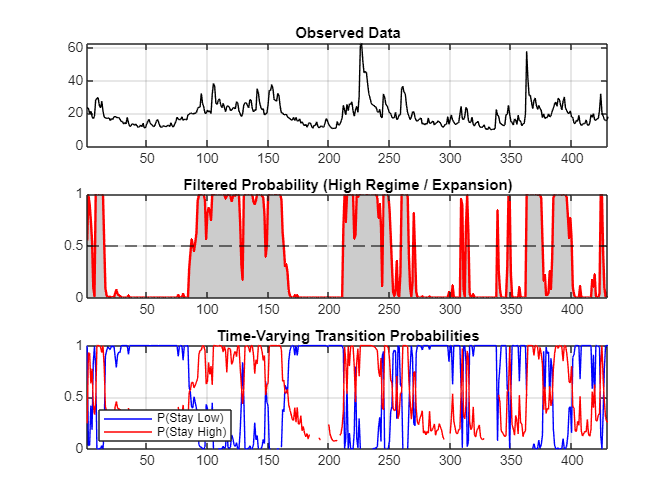


%% 2. RUN ANALYSIS (Volatility Model)
% Configuration for VIX:
% - Volatility Switching
% - k = 0 (No AR lags usually for VIX in this specific framework)

k_vix = 0; 
model_type_vix = 'volatility'; 
run_exog_test_vix = true; 

% Execute analysis using the VIX data
output_vix = run_full_analysis(y_vix, k_vix, model_type_vix, run_exog_test_vix), true;


%% 3. DISPLAY RESULTS: ENDOGENOUS MODEL (Chang et al.)

est_vix = output_vix.params_estimated;
se_vix  = output_vix.se;

% Calculate t-stats
t_stats_vix = est_vix ./ se_vix;

% --- PARAMETER NAMING FOR VOLATILITY MODEL ---
% Structure: [Mu, Sigma_Low, Sigma_High, Alpha, Tau, Rho, Gamma...]
param_names_vix = { ...
    'Mu (Constant)', ...      % Index 1
    'Sigma (Low Vol)', ...    % Index 2
    'Sigma (High Vol)', ...   % Index 3
    'Alpha (Latent)', ...     % Index 4
    'Tau (Threshold)', ...    % Index 5
    'Rho (Endog)'             % Index 6
};

% Add Gamma names dynamically (only if k > 0)
for j = 1:k_vix
    param_names_vix{end+1} = sprintf('Gamma (AR%d)', j);
end

fprintf('\n============================================================\n');

fprintf(' ESTIMATION RESULTS: ENDOGENOUS VOLATILITY MODEL (VIX)\n');

 ESTIMATION RESULTS: ENDOGENOUS VOLATILITY MODEL (VIX)


fprintf('============================================================\n');

fprintf('%-20s | %-10s | %-10s | %-8s\n', 'Parameter', 'Estimate', 'Std.Err', 't-Stat');

Parameter            | Estimate   | Std.Err    | t-Stat  


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------



for i = 1:length(est_vix)
    val = est_vix(i);
    std_err = se_vix(i);
    ts = t_stats_vix(i);
    
    % Significance stars
    sig_star = '';
    if abs(ts) > 1.645, sig_star = '*';   end 
    if abs(ts) > 1.96,  sig_star = '**';  end 
    if abs(ts) > 2.576, sig_star = '***'; end 
    
    fprintf('%-20s | %10.4f | %10.4f | %8.2f %s\n', ...
        param_names_vix{i}, val, std_err, ts, sig_star);
end

Mu (Constant)        |    15.5203 |     0.4362 |    35.58 ***
Sigma (Low Vol)      |     2.8143 |     0.2966 |     9.49 ***
Sigma (High Vol)     |    12.8186 |     0.8460 |    15.15 ***
Alpha (Latent)       |     0.5842 |     0.1864 |     3.13 ***
Tau (Threshold)      |     1.3349 |     0.3230 |     4.13 ***
Rho (Endog)          |     0.9900 |     0.0803 |    12.33 ***


fprintf('------------------------------------------------------------\n');

------------------------------------------------------------


fprintf('Log-Likelihood : %.4f\n', output_vix.loglik);

Log-Likelihood : -1335.2498



% Display LR Test Results
if isfield(output_vix, 'comparison')
    fprintf('\nLIKELIHOOD RATIO TEST (Endogeneity Check - VIX):\n');
    fprintf('  H0: Rho = 0 (Exogenous volatility switching is sufficient)\n');
    fprintf('  LR Statistic: %.4f\n', output_vix.comparison.lr_stat);
    fprintf('  P-Value:      %.4f\n', output_vix.comparison.p_value);
    
    if output_vix.comparison.p_value < 0.05
        fprintf('  -> RESULT: REJECT H0. Endogeneity is significant.\n');
    else
        fprintf('  -> RESULT: FAIL TO REJECT H0. No strong evidence for endogeneity.\n');
    end
end


LIKELIHOOD RATIO TEST (Endogeneity Check - VIX):


  H0: Rho = 0 (Exogenous volatility switching is sufficient)


  LR Statistic: 39.3697


  P-Value:      0.0000


  -> RESULT: REJECT H0. Endogeneity is significant.


fprintf('============================================================\n');



%% 4. DISPLAY RESULTS: EXOGENOUS MODEL (Standard Hamilton Volatility)

if isfield(output_vix, 'comparison') && isfield(output_vix.comparison, 'res_exo')
    
    % Extract Exogenous Results for VIX
    res_exo_vix = output_vix.comparison.res_exo;
    est_exo_vix = res_exo_vix.params;
    se_exo_vix  = res_exo_vix.se;

    % Parameter Names (Same order, but Rho is fixed)
    param_names_exo_vix = param_names_vix;
    param_names_exo_vix{6} = 'Rho (FIXED=0)'; 

    fprintf('\n============================================================\n');
    fprintf(' ESTIMATION RESULTS: EXOGENOUS VOLATILITY MODEL (VIX)\n');
    fprintf('============================================================\n');
    fprintf('%-20s | %-10s | %-10s | %-8s\n', 'Parameter', 'Estimate', 'Std.Err', 't-Stat');
    fprintf('------------------------------------------------------------\n');

    for i = 1:length(est_exo_vix)
        val = est_exo_vix(i);
        std_err = se_exo_vix(i);
        
        if std_err < 1e-6
            fprintf('%-20s | %10.4f | %10s | %8s\n', param_names_exo_vix{i}, val, '(Fixed)', '-');
        else
            ts = val / std_err;
            sig_star = '';
            if abs(ts) > 1.645, sig_star = '*';   end
            if abs(ts) > 1.96,  sig_star = '**';  end
            if abs(ts) > 2.576, sig_star = '***'; end
            
            fprintf('%-20s | %10.4f | %10.4f | %8.2f %s\n', ...
                param_names_exo_vix{i}, val, std_err, ts, sig_star);
        end
    end
    fprintf('------------------------------------------------------------\n');
    fprintf('Log-Likelihood : %.4f\n', res_exo_vix.loglik);
    fprintf('============================================================\n');

else
    fprintf('Warning: Exogenous VIX results not found.\n');
end

 ESTIMATION RESULTS: EXOGENOUS VOLATILITY MODEL (VIX)


Parameter            | Estimate   | Std.Err    | t-Stat  


------------------------------------------------------------


Mu (Constant)        |    15.6962 |     0.3665 |    42.83 ***
Sigma (Low Vol)      |     2.9503 |     0.1792 |    16.46 ***
Sigma (High Vol)     |    13.1109 |     0.7730 |    16.96 ***
Alpha (Latent)       |     0.9900 |     0.0653 |    15.16 ***
Tau (Threshold)      |     2.9152 |     3.1275 |     0.93 
Rho (FIXED=0)        |     0.0000 |     1.0000 |     0.00 


------------------------------------------------------------


Log-Likelihood : -1354.9346


% ==============================================================================
% TABLEAU 1 : HAMILTON (PIB US) - Mean-Switching AR(4)
% ==============================================================================
p_endo = output.params_estimated;            % Paramètres Endogènes
p_exo  = output.comparison.res_exo.params;   % Paramètres Exogènes

fprintf('\n');
fprintf('================================================================================\n');

fprintf(' TABLE 1: MACROECONOMIC APPLICATION (HAMILTON / US GNP)\n');

 TABLE 1: MACROECONOMIC APPLICATION (HAMILTON / US GNP)


fprintf(' Model: Mean-Switching AR(4)\n');

 Model: Mean-Switching AR(4)


fprintf('================================================================================\n');

fprintf('%-25s | %-15s | %-15s\n', 'PARAMETER', 'EXOGENOUS (Rho=0)', 'ENDOGENOUS (Chang)');

PARAMETER                 | EXOGENOUS (Rho=0) | ENDOGENOUS (Chang)


fprintf('--------------------------------------------------------------------------------\n');

--------------------------------------------------------------------------------



% 1. Paramètres Structurels
fprintf('%-25s | %15.4f | %15.4f\n', 'Mu (Recession)',   p_exo(1), p_endo(1));

Mu (Recession)            |         -0.1525 |         -0.0261


fprintf('%-25s | %15.4f | %15.4f\n', 'Mu (Expansion)',    p_exo(2), p_endo(2));

Mu (Expansion)            |          0.5090 |          0.5301


fprintf('%-25s | %15.4f | %15.4f\n', 'Sigma (Volatility)',p_exo(3), p_endo(3));

Sigma (Volatility)        |          0.3336 |          0.3478


fprintf('%-25s | %15.4f | %15.4f\n', 'Alpha (Persistence)', p_exo(4), p_endo(4));

Alpha (Persistence)       |          0.8717 |          0.9331


fprintf('%-25s | %15.4f | %15.4f\n', 'Tau (Threshold)',       p_exo(5), p_endo(5));

Tau (Threshold)           |         -1.1268 |         -0.5122


fprintf('%-25s | %15s | %15.4f\n',   'Rho (Endogeneity)', '0.0000 (Fixed)', p_endo(6));

Rho (Endogeneity)         |  0.0000 (Fixed) |         -0.8507



% 2. Coefficients Auto-Régressifs (Dynamique)
% On détecte k automatiquement (taille totale - 6 paramètres de base)
k_lags = length(p_endo) - 6;

if k_lags > 0
    fprintf('--------------------------------------------------------------------------------\n');
    fprintf(' Auto-Regressive Coefficients (AR)\n');
    for j = 1:k_lags
        idx = 6 + j; % Décalage de 6 (les params de base)
        label = sprintf('Gamma (Lag %d)', j);
        fprintf('%-25s | %15.4f | %15.4f\n', label, p_exo(idx), p_endo(idx));
    end
end

--------------------------------------------------------------------------------


 Auto-Regressive Coefficients (AR)


Gamma (Lag 1)             |          0.0089 |          0.1057
Gamma (Lag 2)             |         -0.0666 |          0.0578
Gamma (Lag 3)             |         -0.2475 |         -0.2783
Gamma (Lag 4)             |         -0.2019 |         -0.1529



fprintf('--------------------------------------------------------------------------------\n');

--------------------------------------------------------------------------------


fprintf('%-25s | %15.4f | %15.4f\n', 'Log-Likelihood', output.comparison.res_exo.loglik, output.loglik);

Log-Likelihood            |        -72.1645 |        -70.9486


fprintf('%-25s | %15s | %15.4f\n',   'LR Test (Stat)',    '-', output.comparison.lr_stat);

LR Test (Stat)            |               - |          2.4319


fprintf('%-25s | %15s | %15.4f\n',   'LR Test (P-Value)', '-', output.comparison.p_value);

LR Test (P-Value)         |               - |          0.1189


fprintf('================================================================================\n');



% ==============================================================================
% TABLEAU 2 : VIX (Finance) - Volatility-Switching
% ==============================================================================
% Note: Ici k=0, donc la section AR ne s'affichera pas automatiquement
p_endo_v = output_vix.params_estimated;
p_exo_v  = output_vix.comparison.res_exo.params;

fprintf('\n\n');
fprintf('================================================================================\n');

fprintf(' TABLE 2: FINANCIAL APPLICATION (VIX INDEX)\n');

 TABLE 2: FINANCIAL APPLICATION (VIX INDEX)


fprintf(' Model: Volatility-Switching (No AR)\n');

 Model: Volatility-Switching (No AR)


fprintf('================================================================================\n');

fprintf('%-25s | %-15s | %-15s\n', 'PARAMETER', 'EXOGENOUS (Rho=0)', 'ENDOGENOUS (Chang)');

PARAMETER                 | EXOGENOUS (Rho=0) | ENDOGENOUS (Chang)


fprintf('--------------------------------------------------------------------------------\n');

--------------------------------------------------------------------------------



fprintf('%-25s | %15.4f | %15.4f\n', 'Mu (Mean Level)',   p_exo_v(1), p_endo_v(1));

Mu (Mean Level)           |         15.6962 |         15.5203


fprintf('%-25s | %15.4f | %15.4f\n', 'Sigma (Calm)',      p_exo_v(2), p_endo_v(2));

Sigma (Calm)              |          2.9503 |          2.8143


fprintf('%-25s | %15.4f | %15.4f\n', 'Sigma (Crisis)',    p_exo_v(3), p_endo_v(3));

Sigma (Crisis)            |         13.1109 |         12.8186


fprintf('%-25s | %15.4f | %15.4f\n', 'Alpha (Persistence)', p_exo_v(4), p_endo_v(4));

Alpha (Persistence)       |          0.9900 |          0.5842


fprintf('%-25s | %15.4f | %15.4f\n', 'Tau (Threshold)',       p_exo_v(5), p_endo_v(5));

Tau (Threshold)           |          2.9152 |          1.3349


fprintf('%-25s | %15s | %15.4f\n',   'Rho (Endogeneity)', '0.0000 (Fixed)', p_endo_v(6));

Rho (Endogeneity)         |  0.0000 (Fixed) |          0.9900



fprintf('--------------------------------------------------------------------------------\n');

--------------------------------------------------------------------------------


fprintf('%-25s | %15.4f | %15.4f\n', 'Log-Likelihood', output_vix.comparison.res_exo.loglik, output_vix.loglik);

Log-Likelihood            |      -1354.9346 |      -1335.2498


fprintf('%-25s | %15s | %15.4f\n',   'LR Test (Stat)',    '-', output_vix.comparison.lr_stat);

LR Test (Stat)            |               - |         39.3697


fprintf('%-25s | %15s | %15.4f\n',   'LR Test (P-Value)', '-', output_vix.comparison.p_value);

LR Test (P-Value)         |               - |          0.0000


fprintf('================================================================================\n');